# Orientation-restricted aromatic core PMFs

We restricted the bare cores to only move in a single dimension and then did two runs, one where they were oriented cofacially, and one where they were not.  There are a number of other orientations they could be interacting in but this is a simplification to see if we can get an order of magnitude comparison between the facial and non-facial interactions.

We open the initial 5 ns runs that may not be converged yet to have a look.

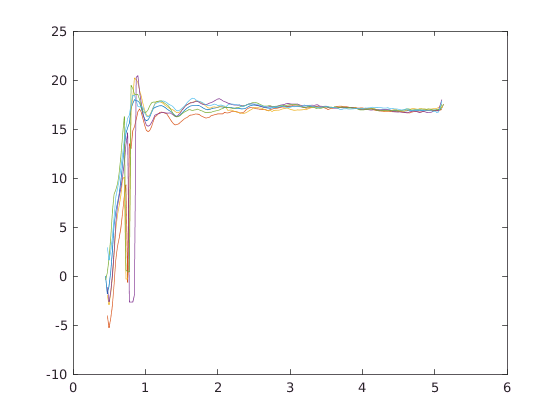

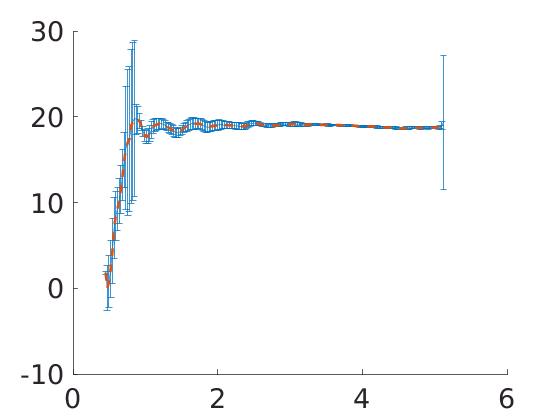

%access appropriate functions
addpath('helper_functions');
%investigate PMFs
fbaseFlat = '/home/rachael/cluster/data/mansbac2/coarsegraining/orient_restrain_mon_PMF/arom_line_restrain/arom_alone_flat/5_umbrella';
fbaseSide = '/home/rachael/cluster/data/mansbac2/coarsegraining/orient_restrain_mon_PMF/arom_line_restrain/arom_alone_side/5_umbrella';
tstart = 1000;
tinterval = 2800;
tend = 15000;
remove_entropic = 0;
profflat = run_block_PMFs(fbaseFlat,tstart,tinterval,tend,remove_entropic,[3 4.5]);

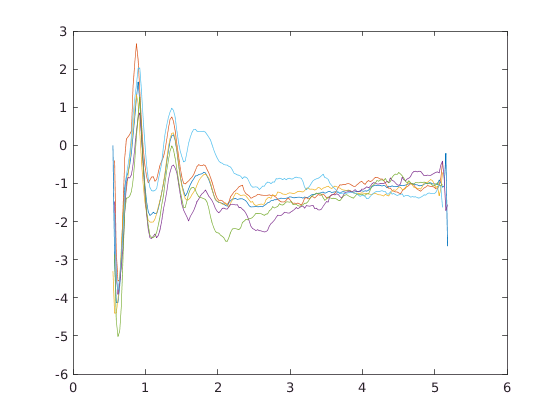

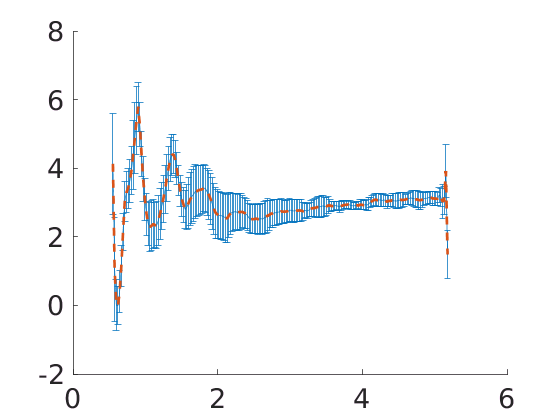

profside = run_block_PMFs(fbaseSide,tstart,tinterval,tend,remove_entropic,[3 4.5]);

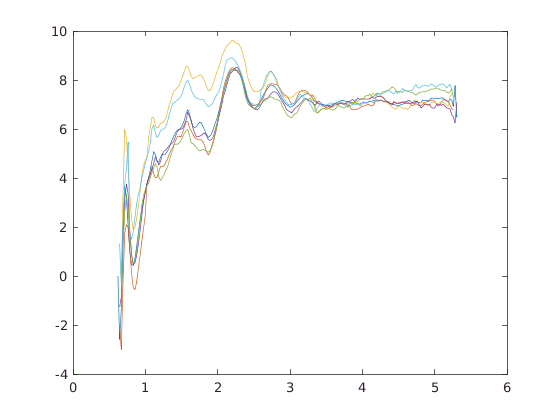

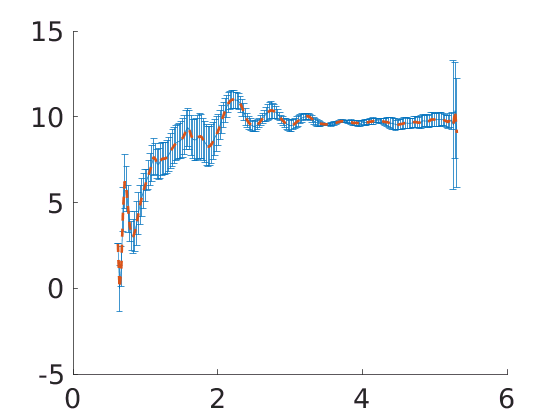

fbaseSlide1 = '/home/rachael/cluster/scratch/ramansbach/o4rient_restrain_mon_PMF/arom_line_restrain/arom_alone_side_end/5_umbrella';
fbaseSlide2 = '/home/rachael/cluster/scratch/ramansbach/orient_restrain_mon_PMF/arom_line_restrain/arom_alone_side_end_far/5_umbrella';
tstart = 0;
tinterval = 1000;
tend = 5000;
remove_entropic = 0;
profslide1 = run_block_PMFs(fbaseSlide1,tstart,tinterval,tend,remove_entropic,[3 4.5]);

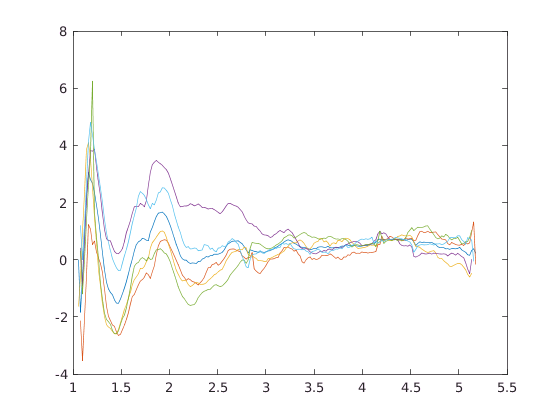

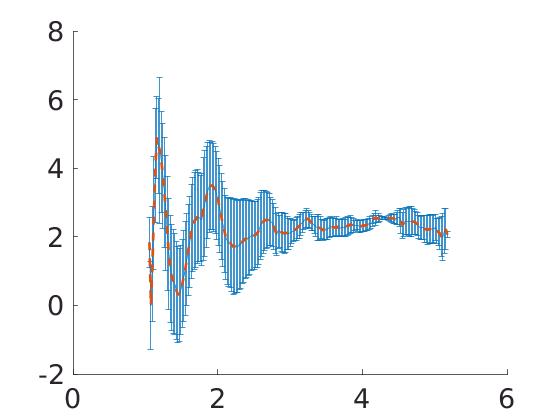

profslide2 = run_block_PMFs(fbaseSlide2,tstart,tinterval,tend,remove_entropic,[4 4.5]);

Note, firstly, that the drop for the perfect alignment is ~18 kT (~6kT/core), compared to ~12 kT (~4kT/core) for tangled up cores.  This puts us in the realm of ~3-3.7 per AA bead, rather than 1.85.

Then for the side-on interactions, there is a drop of ~0.7 for the minimum at 1 nm (which for beads with a radius of 0.5 is about where the LJ minimum will be.)  This leads to a per-bead drop of ~0.23 at its most unfavorable orientation versus a drop of ~3 for its most favorable.  Another way to estimate this is simply to consider the interaction of the single SC5 bead interacting with another single SC5 bead, which is 3.5 kJ/mol * 0.75 at its minimum = 2.625 kJ/mol ~ 1 kT in the units of this patchy system and which approximately corresponds to the interaction of a single side of one ring with the single side of another.  This corresponds reasonably well with the drop at 0.5 nm of ~3 kT (or about 1 kT/core).

Now allowing them to configure however they want gives the 1.85 drop.  Really what we want to do is redistribute this and our estimations little bit, so it may be reasonable to estimate a per-bead drop of ~0.5 (order of magnitude at least) for each aromatic core whose side interactions with another core (ie four cores in a line will be different from four cores where some are sidealong.)  So let's go ahead and test BB = 0.6 as well (average the 0.7 and 3 kT drops from the above considerations).

The shape of the central cores will change this, to an extent, but this is still quite approximate.